# Differential Drive Robot

Optimize the drive motors of the robot according to the provided waypoints and its conception.

Based on 

## Problem Definition

### Robot Kinematic Parameters

robot.R = 0.08;   %Wheel radius (m)
robot.M = 2;      %Robot Mass (kg)
robot.d = 0;      %Mass center/wheel excentricity (m)
robot.L = 0.15;   %Robot Semi-Length (m)
robot.J = 1/2*robot.M*robot.L^2;    %Robot inertial moment (kg.m^2)

### Robot Electrical Parameters

robot.N = 1;      %Motor Gear Ratio ()
robot.Ra = 5.8536585365853666;  %Motor Armature Resistance (Ohms)
robot.La = 4.8e-3;  %Motor Armature Inductance (H)
robot.Kt = 0.52857142857142858;  %Motor Torque Constant (N.m/A)
robot.Kb = 1.8918918918918919;  %Motor Back EMF Constant (V.s/rad)

### Robot Initial States

The robot position is computed in absolute according to the frame at the South/West of the "Table" (considered as the authorized area)

xMax = [340 210]*1e-2; %Table Length(X)/Width(Y) (m)
x0 = [20 60]*1e-2;  %Starting Position (m)
theta0 = deg2rad(30);        %Starting Heading (rad) trigo from East

### Requested Waypoints

wp = [100 70 deg2rad(0);  %Waypoints in the frame X/Y (m) and direction (rad)
      150 40 deg2rad(-45)
      180 150 deg2rad(90)];
wp(:,1:2) = wp(:,1:2)*1e-2;

## Compute Optimization Problem

soln = diffDriveOptim(robot,xMax,x0,theta0,wp);

~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
Running OptimTraj, iteration 1
  -> Transcription via trapezoid method, nGrid = 12

Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to satisfy the bounds.
                                                               Norm of First-order
 Iter  Func-count            Fval Feasibility  Step Length        step  optimality
    0         111    3.524590e+00   1.397e+03                            1.000e+00
    1         222    6.561597e-02   2.554e+01    1.000e+00   4.957e+00   1.195e+03
    2         333    4.995802e-02   4.240e+00    1.000e+00   2.181e+01   3.686e+03
    3         444    3.518888e-02   8.807e-01    1.000e+00   5.396e+00   8.749e+03
    4         555    2.556860e-02   5.900e-01    1.000e+00   3.153e+00   1.905e+04
    5         666    2.271027e-02   5.900e-01    1.000e+00   1.763e+00   3.980e+04
    6         777    2.141104e-02   5.900e-01    1.000e+00   5.625e-01   8.165e+04
    7         894

## Visualisation

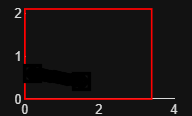

figure(1); clf; hold on;

rectangle('Position',[0,0,xMax],'EdgeColor','r','LineWidth',1);

soln = soln{1};

t = linspace(soln.grid.time(1), soln.grid.time(end), 150);
z = soln.interp.state(t);
x = z(4,:);
y = z(5,:);
th = z(3,:);
u = soln.interp.control(t);

tGrid = soln.grid.time;
xGrid = soln.grid.state(4,:);
yGrid = soln.grid.state(5,:);
thGrid = soln.grid.state(3,:);
uGrid = soln.grid.control;

% Plot the entire trajectory
plot(x,y,'r-','LineWidth',3);

% Plot the grid points:
plot(xGrid, yGrid, 'ko','MarkerSize',5,'LineWidth',3);

% Plot the start and end points:
plot(x([1,end]), y([1,end]),'ks','MarkerSize',12,'LineWidth',3);

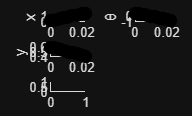


% Plot the state and control:
figure(2); clf; 

subplot(3,2,1); hold on;
plot(t,x);
plot(tGrid,xGrid,'ro','MarkerSize',5,'LineWidth',3);
ylabel('x');

subplot(3,2,3); hold on;
plot(t,y);
plot(tGrid,yGrid,'ro','MarkerSize',5,'LineWidth',3);
ylabel('y');

subplot(3,2,2); hold on;
plot(t,th);
plot(tGrid,thGrid,'ro','MarkerSize',5,'LineWidth',3);
ylabel('θ');

subplot(3,2,5); hold on;

plot(t,z(1,:));
plot(t,z(2,:));
plot(tGrid,soln.grid.state(1,:),'ro','MarkerSize',5,'LineWidth',3);
plot(tGrid,soln.grid.state(2,:),'ro','MarkerSize',5,'LineWidth',3);
ylabel('v & w');

subplot(3,2,4); hold on;
plot(t,u(1,:));
plot(t,u(2,:));
plot(tGrid,uGrid(1,:),'ro','MarkerSize',3,'LineWidth',3);
plot(tGrid,uGrid(2,:),'ro','MarkerSize',3,'LineWidth',3);
plot(t,u);
ylabel('u');
